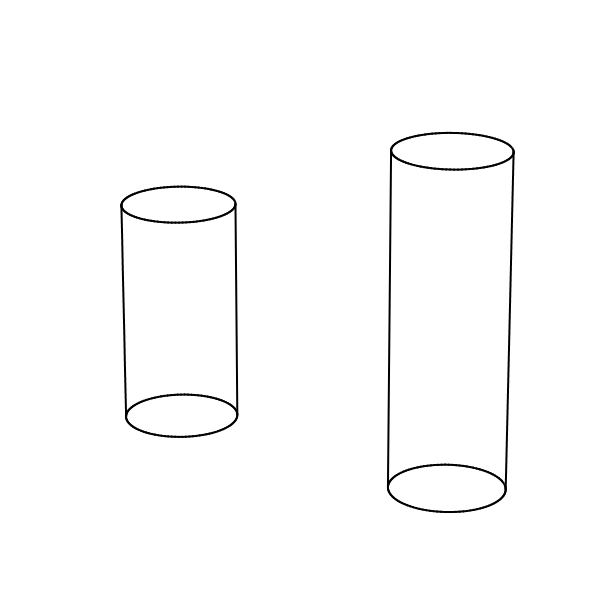

h_fig = figure(1);
clf
set(h_fig,'Visible','on')
set(h_fig, "Position", [1487 408 600 600])
set(h_fig,'color','w');
camproj('perspective')
axis equal off
%axis on

view(80,20)
hold on

update_list = {
diagrams.cylinder([4;4;1], [0;0;1], 3, 1);
diagrams.cylinder([0;0;0], [0;0;1], 2, 1);
};

diagrams.runall(update_list)

hold off
set(h_fig,'KeyPressFcn',@(~,~)diagrams.runall(update_list));
set(h_fig, 'renderer', 'painters')